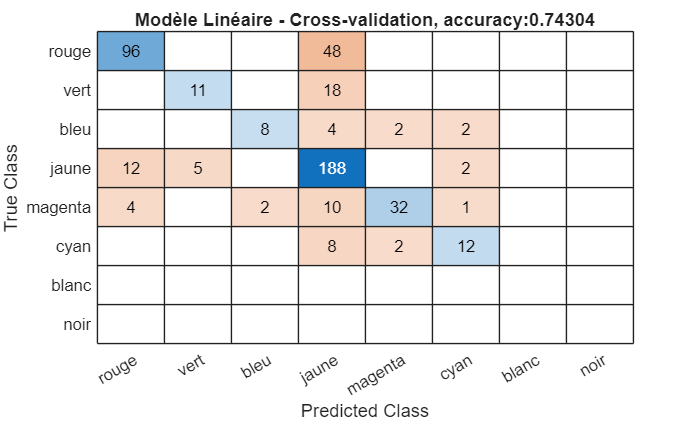

clear 
%% 1. Chargement des données
path = 'E:\Data\Aurelie\data\nocues\444119\220919_plane0\';
load(strcat(path ,'Fall.mat'));

% path_colorcell = "E:\Data\Aurelie\data\chroms\119\220919\registration\colorcell.mat";
path_colorcell = "E:\Data\Aurelie\data\chroms\119\220919\registration\colorcell_exvivo_validatedprediction_20260507.mat";

% path_colorcell ="E:\Data\Aurelie\data\chroms\119\220919\registration\colorcell_exvivo_biapy_20260424.mat";

load (path_colorcell);

blue = imread(strcat(path,'aligned_blue.tif'));
red = imread(strcat(path,'aligned_red.tif'));
% red890 = imread([path,'red890.tif']);
green = imread(strcat(path,'aligned_green.tif'));
green_dec  = imread(strcat(path,'deconv_green.tif'));
calcium = imread(strcat(path,'calcium.tif'));
composite = imread(strcat(path,'composite.tif'));

%% 2. Masques et Centroïdes
% Load calcium mask from suite2p (from Fall.mat)
m = 0;
NCell = sum(iscell(:,1)>0);

for n = 1 : length(stat)
    if iscell(n,1) == 1
        m = m + 1;
        outline_gcampx(m) = {double(stat{1, n}.xext + 1)};
        outline_gcampy(m) = {double(stat{1, n}.yext + 1)};
        neuropil(m) = {stat{1, n}.neuropil_mask};
        Coomasqx(m) = {double(stat{1, n}.xpix + 1)}; % +1 to adpat suite2p output ONLY 1 ??????
        Coomasqy(m) = {double(stat{1, n}.ypix + 1)};
    end
end

% Calculation of centroid
% tic
gcamp_centroid = zeros(NCell,2);
for n = 1:NCell
    gcamp_centroid(n,:) = [mean(cell2mat(Coomasqx(1,n))), mean(cell2mat(Coomasqy(1,n)))];
end

%% 3. Extraction des Intensités 
% Conversion en double pour les calculs d'intensité
blue_d = double(blue);
red_d = double(red);
green_d = double(green);
green_dec_d = double(green_dec);
calcium_d = double(calcium);

% Dimensions de l'image (pour éviter les débordements de bord)
[imgH, imgW] = size(blue_d); % toutes les images ont la même taille

radius = 2; % 3 pixels autour du centroïde

% Matrice résultante : NCell x 5
% colonnes = [intensité_blue, intensité_red, intensité_green, intensité_calcium]
intensity_features = zeros(NCell, 5);

for n = 1:NCell
    % Centroïde : gcamp_centroid(n,1) = x (colonne), gcamp_centroid(n,2) = y (ligne)
    cx = round(gcamp_centroid(n, 1)); % colonne (x)
    cy = round(gcamp_centroid(n, 2)); % ligne (y)
    
    % Définition de la fenêtre, clampée aux bords de l'image
    col_min = max(1, cx - radius);
    col_max = min(imgW, cx + radius);
    row_min = max(1, cy - radius);
    row_max = min(imgH, cy + radius);
    
    % Extraction du patch pour chaque canal
    patch_blue = blue_d (row_min:row_max, col_min:col_max);
    patch_red = red_d (row_min:row_max, col_min:col_max);
    patch_green = green_d (row_min:row_max, col_min:col_max);
    patch_calcium = calcium_d(row_min:row_max, col_min:col_max);
    patch_green_dec = green_dec_d(row_min:row_max, col_min:col_max);
        
    % Intensité = moyenne sur tous les pixels du patch
    intensity_features(n, 1) = mean(patch_blue(:));
    intensity_features(n, 2) = mean(patch_red(:));
    intensity_features(n, 3) = mean(patch_green(:));
    intensity_features(n, 4) = mean(patch_calcium(:));
    intensity_features(n, 5) = mean(patch_green_dec(:));
end

% % Variante : intensité sur les pixels exacts du masque suite2p
% intensity_features = zeros(NCell, 5); % Initialisation propre de la matrice
% for n = 1:NCell
%     px = cell2mat(Coomasqx(1,n)); % vecteur de colonnes
%     py = cell2mat(Coomasqy(1,n)); % vecteur de lignes
% 
%     % Protection contre les dépassements de masque hors image
%     px = max(1, min(imgW, px));
%     py = max(1, min(imgH, py));
% 
%     idx = sub2ind([imgH, imgW], py, px); % indices linéaires
% 
%     intensity_features(n, 1) = mean(blue_d(idx));
%     intensity_features(n, 2) = mean(red_d(idx));
%     intensity_features(n, 3) = mean(green_d(idx));
%     intensity_features(n, 4) = mean(calcium_d(idx));
%     intensity_features(n, 5) = mean(green_dec_d(idx));
% end

% Table lisible pour vérification
T = array2table(intensity_features, ...
    'VariableNames', {'I_blue', 'I_red', 'I_green', 'I_calcium', 'I_green_dec'});
% disp(T)

%% 4. Préparation pour la Classification
% X de base (tes 5 intensités brutes)


X_base = intensity_features; 

X_norm = normalize(X_base, 'range'); 
I_blue      = X_norm(:, 1);
I_red       = X_norm(:, 2);
I_green     = X_norm(:, 3);
I_calcium   = X_norm(:, 4);
I_green_dec = X_norm(:, 5);

% X = [I_blue, I_red, I_green, I_calcium, I_green_dec];
ratio_RGd = I_red   ./ (I_green_dec + 0.01);
ratio_BGd = I_blue  ./ (I_green_dec + 0.01);
ratio_RB  = I_red   ./ (I_blue + 0.01);
ratio_GB  = I_green ./ (I_blue + 0.01);

X = [I_blue, I_red, I_green, I_calcium, I_green_dec, ...
     ratio_RGd, ratio_BGd, ratio_RB, ratio_GB];

% % On extrait les colonnes pour que ce soit lisible
% I_blue  = X_base(:, 1);
% I_red   = X_base(:, 2);
% I_green = X_base(:, 3);
% I_gcamp = X_base(:, 4); % Le vert propre
% I_green_dec = X_base(:, 5); % Le vert propre
% 
% %On calcule des ratios (le +1 sert juste à éviter de diviser par zéro)
% ratio_Red_GreenDec = I_red ./ (I_green_dec + 1);
% ratio_Blue_GreenDec = I_blue ./ (I_green_dec + 1);
% 
% % On assemble TOUT dans X : les 5 intensités + les 2 ratios
% X = [X_base, ratio_Red_GreenDec, ratio_Blue_GreenDec];

% X = X_base(:,1:5);



% Supprimer la catégorie 'noir' devenue vide (important pour confusionchart)

% --- Partition sur les données filtrées ---

rng(1);
K = 10;

Y_num = str2double(string(colorcell));

% On recrée la variable catégorielle proprement avec les 8 couleurs
classNames = {'rouge','vert','bleu','jaune','magenta','cyan','blanc','noir'};
Ycat = categorical(Y_num, 1:8, classNames);

maskNoNoir = Ycat ~= 'noir';   % vecteur logique : true pour toutes les classes sauf noir
X_filt   = X(maskNoNoir, :);   % features filtrées
X = X_filt;

Ycat_filt = Ycat(maskNoNoir);  % labels filtrés
Ycat = Ycat_filt;

% Création de la partition stratifiée
cvp = cvpartition(Ycat, 'KFold', K);

%% ================= MODÈLE LINÉAIRE =================
CVMdlLin = fitcdiscr(X, Ycat, 'DiscrimType', 'linear', 'CVPartition', cvp);
accLin = 1 - kfoldLoss(CVMdlLin);
% fprintf('Accuracy CV modele lineaire = %.3f\n', accLin);

% Récupération des prédictions du modèle linéaire
YPredLin = kfoldPredict(CVMdlLin);

% Affichage de la matrice de confusion Linéaire3
figure;
confusionchart(Ycat, YPredLin);
title(strcat('Modèle Linéaire - Cross-validation, accuracy:', num2str(accLin)));

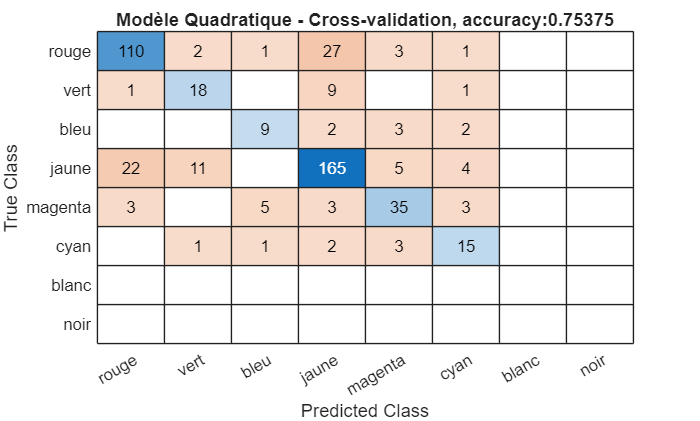


%% ================= MODÈLE QUADRATIQUE =================
% Souvent, s'il y a peu d'exemples dans certaines classes, le quadratique pur plante.
% On utilise 'pseudoQuadratic' qui est plus robuste tout en gardant des frontières courbes.
CVMdlQuad = fitcdiscr(X, Ycat, 'DiscrimType', 'pseudoQuadratic', 'CVPartition', cvp);
accQuad = 1 - kfoldLoss(CVMdlQuad);
% fprintf('Accuracy CV modele quadratique = %.3f\n', accQuad);

YPredQuad = kfoldPredict(CVMdlQuad);

figure;
confusionchart(Ycat, YPredQuad);
title(strcat('Modèle Quadratique - Cross-validation, accuracy:', num2str(accQuad)));

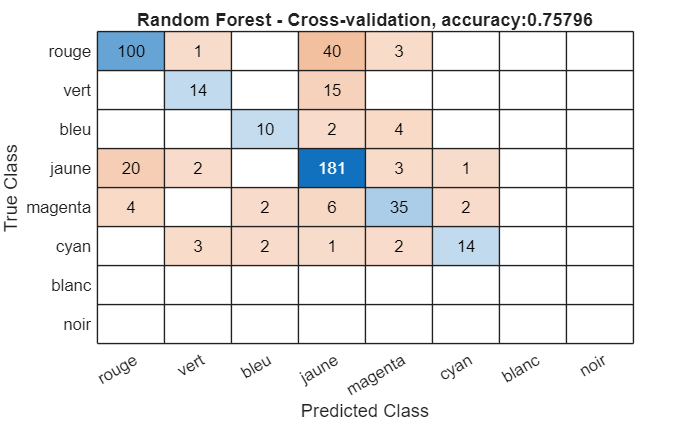



%% ================= RANDOM FOREST =================
YPredRF = categorical(strings(size(Ycat)), categories(Ycat));
scoresRF = zeros(size(X,1), length(categories(Ycat))); % Matrice pour stocker les probabilités
accFoldRF = zeros(K,1);

for k = 1:K
    idxTrain = training(cvp, k);
    idxTest = test(cvp, k);
    
    % Entraînement du modèle sur le fold courant
    % MdlRF = TreeBagger(200, X(idxTrain,:), Ycat(idxTrain), ...
    %     'Method','classification');
        MdlRF = TreeBagger(200, X(idxTrain,:), Ycat(idxTrain), ...
        'Method','classification','MinLeafSize', 10);
    
    % Prédiction sur le fold de test
    [yhat, scores] = predict(MdlRF, X(idxTest,:));
    yhat = categorical(yhat, categories(Ycat), categories(Ycat));
    
    % Stockage des résultats de classe
    YPredRF(idxTest) = yhat;
    
    % --- CORRECTION DU RANGEMENT DES SCORES ---
    % MdlRF.ClassNames contient les noms des classes réellement vues par l'arbre (ex: 6 classes)
    % ismember trouve à quelles colonnes (parmi les 8) elles correspondent
    [~, classIndices] = ismember(MdlRF.ClassNames, categories(Ycat));
    
    % On range les probabilités de la prédiction dans ces colonnes exactes
    scoresRF(idxTest, classIndices) = scores; 
    % ------------------------------------------
    
    accFoldRF(k) = mean(yhat == Ycat(idxTest));
end

accRF = mean(accFoldRF);
% fprintf('Accuracy CV random forest = %.3f\n', accRF);

% Affichage de la matrice de confusion Random Forest
figure;
confusionchart(Ycat, YPredRF);
title(strcat('Random Forest - Cross-validation, accuracy:', num2str(accRF)));

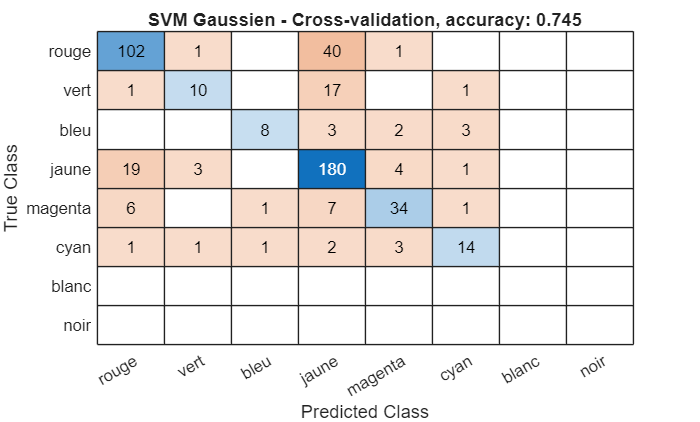

%% ================= MODÈLE SVM (Noyau Gaussien RBF) =================
% 1. On crée le "template" du SVM avec un noyau RBF (Gaussien)
% On laisse MATLAB choisir automatiquement l'échelle optimale du noyau ('auto')
tSVM = templateSVM('KernelFunction', 'gaussian', 'KernelScale', 'auto');

% 2. On entraîne le modèle multiclasse avec fitcecoc et notre partition K-Fold
CVMdlSVM = fitcecoc(X, Ycat, ...
    'Learners', tSVM, ...
    'CVPartition', cvp);

% 3. On calcule l'Accuracy
accSVM = 1 - kfoldLoss(CVMdlSVM);
% fprintf('Accuracy CV modele SVM Gaussien = %.3f\n', accSVM);

% 4. Récupération des prédictions pour la matrice de confusion
YPredSVM = kfoldPredict(CVMdlSVM);

% Affichage de la matrice de confusion SVM
figure;
confusionchart(Ycat, YPredSVM);
title(sprintf('SVM Gaussien - Cross-validation, accuracy: %.3f', accSVM));

%% Résumé final
Results = table(["Lineaire";"quadratic"; "RandomForest"; "SVM_Gaussien"], ...
    [accLin;accQuad; accRF; accSVM], ...
    'VariableNames', {'Modele','AccuracyCV'});
disp('--- COMPARAISON FINALE DES MODELES ---');

--- COMPARAISON FINALE DES MODELES ---


disp(Results);

        Modele        AccuracyCV
    ______________    __________

    "Lineaire"         0.74304  
    "quadratic"        0.75375  
    "RandomForest"     0.75796  
    "SVM_Gaussien"     0.74518  



MdlLin_Final = fitcdiscr(X, Ycat, 'DiscrimType', 'linear');

% 2. Le modèle Random Forest Final (pour faire de futures prédictions)
% MdlRF_Final = TreeBagger(200, X_filt, Ycat_filt, 'Method', 'classification');
K1 = 1; % Index de la première classe
K2 = 2; % Index de la deuxième classe

% 3. Affichage des paramètres de l'équation :
fprintf('--- Équation linéaire séparant la classe %d et la classe %d ---\n', K1, K2);

--- Équation linéaire séparant la classe 1 et la classe 2 ---



% La constante (l'ordonnée à l'origine)
Constante = MdlLin_Final.Coeffs(K1, K2).Const;
fprintf('Constante = %.4f\n', Constante);

Constante = 1.7935



% Les coefficients pour chaque variable (dans l'ordre de ton tableau X)
Coefficients = MdlLin_Final.Coeffs(K1, K2).Linear;
disp('Coefficients des variables :');

Coefficients des variables :


disp(Coefficients);

   -3.1290
   14.7693
 -202.3182
   73.7389
  140.6936
   -0.1087
   -0.0583
    1.4126
   -2.3591



% numRepeats = 5; % Nombre de répétitions
% K = 10;         % Nombre de plis
% 
% % Tableaux pour stocker les scores de chaque répétition
% acc_lin = zeros(numRepeats,1);
% acc_quad = zeros(numRepeats,1);
% acc_rf = zeros(numRepeats,1);
% acc_svm = zeros(numRepeats,1);
% 
% for r = 1:numRepeats
%     % cvpartition va générer un nouveau découpage aléatoire à chaque tour de boucle
%     cvp = cvpartition(Ycat_filt, 'KFold', K);
% 
%     % Linéaire
%     MdlLin = fitcdiscr(X_filt, Ycat_filt, 'DiscrimType', 'linear', 'CVPartition', cvp);
%     acc_lin(r) = 1 - kfoldLoss(MdlLin);
% 
%     % Quadratique
%     MdlQuad = fitcdiscr(X_filt, Ycat_filt, 'DiscrimType', 'pseudoQuadratic', 'CVPartition', cvp);
%     acc_quad(r) = 1 - kfoldLoss(MdlQuad);
% 
%     % Random Forest (on peut utiliser une boucle ou la fonction fitcensemble)
%     MdlRF = fitcensemble(X_filt, Ycat_filt, 'Method', 'Bag', 'NumLearningCycles', 200, 'CVPartition', cvp);
%     acc_rf(r) = 1 - kfoldLoss(MdlRF);
% 
%     % SVM Gaussien
%     tSVM = templateSVM('KernelFunction', 'gaussian', 'KernelScale', 'auto');
%     MdlSVM = fitcecoc(X_filt, Ycat_filt, 'Learners', tSVM, 'CVPartition', cvp);
%     acc_svm(r) = 1 - kfoldLoss(MdlSVM);
% end
% 
% % Résultats moyens
% fprintf('Score Linéaire moyen : %.3f\n', mean(acc_lin));
% fprintf('Score Quadratique moyen : %.3f\n', mean(acc_quad));
% fprintf('Score Random Forest moyen : %.3f\n', mean(acc_rf));
% fprintf('Score SVM moyen : %.3f\n', mean(acc_svm));

% %% Résumé final
% Results = table(["Lineaire";"quadratic"; "RandomForest"; "SVM_Gaussien"], ...
%     [mean(acc_lin);mean(acc_quad); mean(acc_rf); mean(acc_svm)], ...
%     'VariableNames', {'Modele','AccuracyCV'});
% disp('--- COMPARAISON FINALE DES MODELES ---');
% disp(Results);

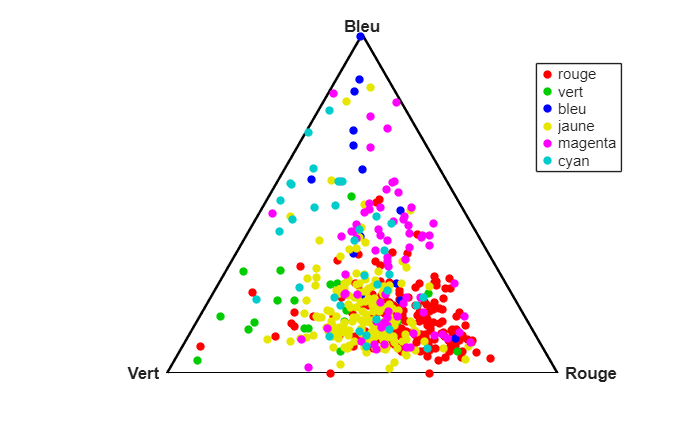

%% --- REPRÉSENTATION DANS UN TRIANGLE DE MAXWELL ---

% 1. Récupération des intensités brutes pour les 3 canaux de base
% On utilise X_base (avant normalisation Min-Max) pour garder les vrais ratios physiques

% R = X_base(maskNoNoir, 2); % I_red
% G = X_base(maskNoNoir, 3); % I_green_dec (le vert propre)
% B = X_base(maskNoNoir, 1); % I_blue
B = X_norm(:, 1);
R = X_norm(:, 2);
G = X_norm(:, 3);
I_calcium   = X_norm(:, 4);
I_green_dec = X_norm(:, 5);

clear colorcell
% path_colorcell = "E:\Data\Aurelie\data\chroms\119\220919\registration\colorcell_invivo_20260424.mat";
% path_colorcell = "E:\Data\Aurelie\data\chroms\119\220919\registration\colorcell_exvivo_validatedprediction_20260424.mat";
path_colorcell ="E:\Data\Aurelie\data\chroms\119\220919\registration\colorcell_exvivo_biapy_20260424.mat";
load (path_colorcell)
Y_num = str2double(string(colorcell));


% On recrée la variable catégorielle proprement avec les 8 couleurs
classNames = {'rouge','vert','bleu','jaune','magenta','cyan','blanc','noir'};
Ycat = categorical(Y_num, 1:8, classNames);

% 2. Calcul des coordonnées chromatiques (r, g, b)
% La somme r + g + b fera toujours 1
Somme = R + G + B + 0.001; % +0.001 pour éviter la division par zéro
r = R ./ Somme;
g = G ./ Somme;
b = B ./ Somme;

% 3. Projection géométrique dans un triangle équilatéral 2D
% Sommets : Vert=(0,0), Rouge=(1,0), Bleu=(0.5, sqrt(3)/2)
X_tri = r + (b * 0.5);
Y_tri = b * (sqrt(3) / 2);

% 4. Préparation des couleurs d'affichage pour les 7 classes
% L'ordre correspond à tes categories : rouge, vert, bleu, jaune, magenta, cyan, blanc
couleurs_affichage = [
    1.0  0.0  0.0;  % 1. Rouge
    0.0  0.8  0.0;  % 2. Vert
    0.0  0.0  1.0;  % 3. Bleu
    0.9  0.9  0.0;  % 4. Jaune
    1.0  0.0  1.0;  % 5. Magenta
    0.0  0.8  0.8;  % 6. Cyan
    0.6  0.6  0.6;  % 7. Blanc (gris)
    0.0  0.0  0.0   % 8. Noir (NOUVEAU)
];

% 5. Dessin de la figure
figure('Name', 'Triangle de Maxwell', 'Color', 'w');
hold on;

% Dessin des bordures du triangle
plot([0, 1, 0.5, 0], [0, 0, sqrt(3)/2, 0], 'k-', 'LineWidth', 1.5);

% Ajout du texte aux sommets
text(1.02, 0, 'Rouge', 'FontWeight', 'bold', 'HorizontalAlignment', 'left');
text(-0.02, 0, 'Vert', 'FontWeight', 'bold', 'HorizontalAlignment', 'right');
text(0.5, sqrt(3)/2 + 0.02, 'Bleu', 'FontWeight', 'bold', 'HorizontalAlignment', 'center');

% 6. Tracer les cellules (Nuage de points)
% gscatter regroupe automatiquement les points par classe (Ycat_filt)
gscatter(X_tri, Y_tri, Ycat, couleurs_affichage, '.', 15);

% title('Répartition chromatique des cellules (Triangle de Maxwell)');
axis equal; % Pour que le triangle ne soit pas déformé
axis off;   % Cacher les axes X et Y classiques
hold off;